# Model Checker

This collection of classes could be used to generate models that fulfill special properties that prohibit some cases like: "Don't cross the crossroad when there is an other vehicle to collide with.".

## General concepts

The model checker allows to parallelize transition systems and synthesize them with büchi automatas to apply safety properties. This is used in an example to show how the state systems are used.

### Transition System

A transition system could be described as a tupel $\(TS = (S, Act, \rightarrow, I, AP, L)\)$, where

- $\(S\)$ is the set of all states,

- $\(Act\)$ is the set of all actions,

- $\(\rightarrow \subseteq S \times Act \times S \)$ is the transition relation,

- $\(I \subseteq S\)$ is the set of all initial states,

- $\(AP\)$ is the set of all atomic propositions and 

- $\(L: S \rightarrow 2^{AP}\)$ is a labeling function using the set of atomic propositions.

#### Functions

- parallelize - Parallelize two or more transition systems.

- plot - Plot transition system as digraph.

- synthesizeWithBA - Synthesize the transition system with a büchi automata.

#### Parallelization

Two or more transition systems that can take actions at the same time can be parallized to get a system showing all possible states and transitions from all subsystems. For that the transition systems get parallelized as follows:

- 
$$\(S_\parallel = S_1 \times S_2$$


- 
$$\(Act_\parallel = Act_1 \cup Act_2$$


- If $\(\alpha \in Act_1, \beta \in Act_2, s_1$ $\longrightarrow^{\alpha }$ $s'_1 \) with action \(\alpha\)$and $ \(s_2$ $\longrightarrow^{\beta }$ $ s'_2$, then $ \( \langle s_1,s_2 \rangle $$\longrightarrow^{\alpha }$ $\langle s'_1,s_2 \rangle,\langle s_1,s_2 \rangle $$\longrightarrow^{\beta }$ $\langle s_1,s'_2 \rangle\)$

- 
$$\(I_\parallel = I_1 \times I_2$$


- 
$$\(AP_\parallel = AP_1 \cup AP_2$$


- A label for a parallelized state is made by this rule: $\(L(\langle s_1,s_2 \rangle) = L_1(s_1) \cup L_2(s_2) \)$

#### Synthesize with BA

To get a transition system that fulfills a safety property described with a büchi automata both systems have to be synthesized.

The synthesized system $\(TS' = TS \otimes \mathcal{A} \)$ could be described with following equations:

- 
$$\(S' = S \times Q\)$$


- 
$$\( \forall s,t \in S, q,p \in Q \text{ with } s 
$$

$$\longrightarrow^{\alpha }$$
 
$$t \text{ and } q $$
 
$$\longrightarrow^{L\left(t\right)}$$

$$p \text{, then exists a transition } \langle s,q \rangle $$
 
$$\overset{\alpha }{\longrightarrow^{\prime } }$$

$$\langle t,p \rangle \)
$$


- 
$$I' = \{\langle s_0,q \rangle : s_0 \in I \text{ and }\exists q_0 \in Q_0 \text{ such that } q_0$$
 
$$\longrightarrow^{L\left(s_0 \right)}$$
 
$$q\}\$$


- 
$$\(AP' = Q\)$$


- 
$$L' : S \times Q \rightarrow 2^Q \text{ und } L'(\langle s,q \rangle) = \{q\} 
$$


Only states and transitions on a path that lead to an accepted state are allowed in the resulting transition system that fulfills the buchi automata.

Accepted states have following properties:

- 
$$L'(\langle s,q\rangle) \in F$$


- The state $  \( \langle s,q \rangle \) $could be reaced that means it exists a finite path fragment  $\(\pi_p'\)$ from any initial state $ \(\langle s_0,q_0 \rangle \in I'\)$ to $\(\langle s,q \rangle\)$ in$ \(TS'\)
$.

- The state $  \( \langle s,q \rangle \) $is in a direct cycle that means there exists a finite path fragment $\(\pi_c'\)$ from a state $ \(\langle s',q' \rangle \in Post(\langle s,q \rangle)\)$ to$\(\langle s,q \rangle\)$ in $ \(TS'\)
$.

### Büchi Automata

A büchi automata system could be described as a tupel $\(\mathcal{A} = (Q, \Sigma,\delta,Q_0,F)\)$, where

- $\(Q\)$ is the set of finite states,

- $\(\Sigma\)$ is the set of all symbols,

- $\(\delta \subseteq Q \times \Sigma \times Q\)$ is the transition relation,

- $\(Q_0 \subseteq Q \)$ is the set of all initial states,

- $\(F \subseteq Q \) $ is the set of all final states, also called accepted states.

### Example: Frogs and Leaps

A frog wants to jump along a Path $\(p\9$. At path segment $\(p_4\)
$ he runs into a problem. There is a river and only every second time is a leafe coming that he can use to cross the river. If there is no leafe he has to wait, because he is afraid of water.

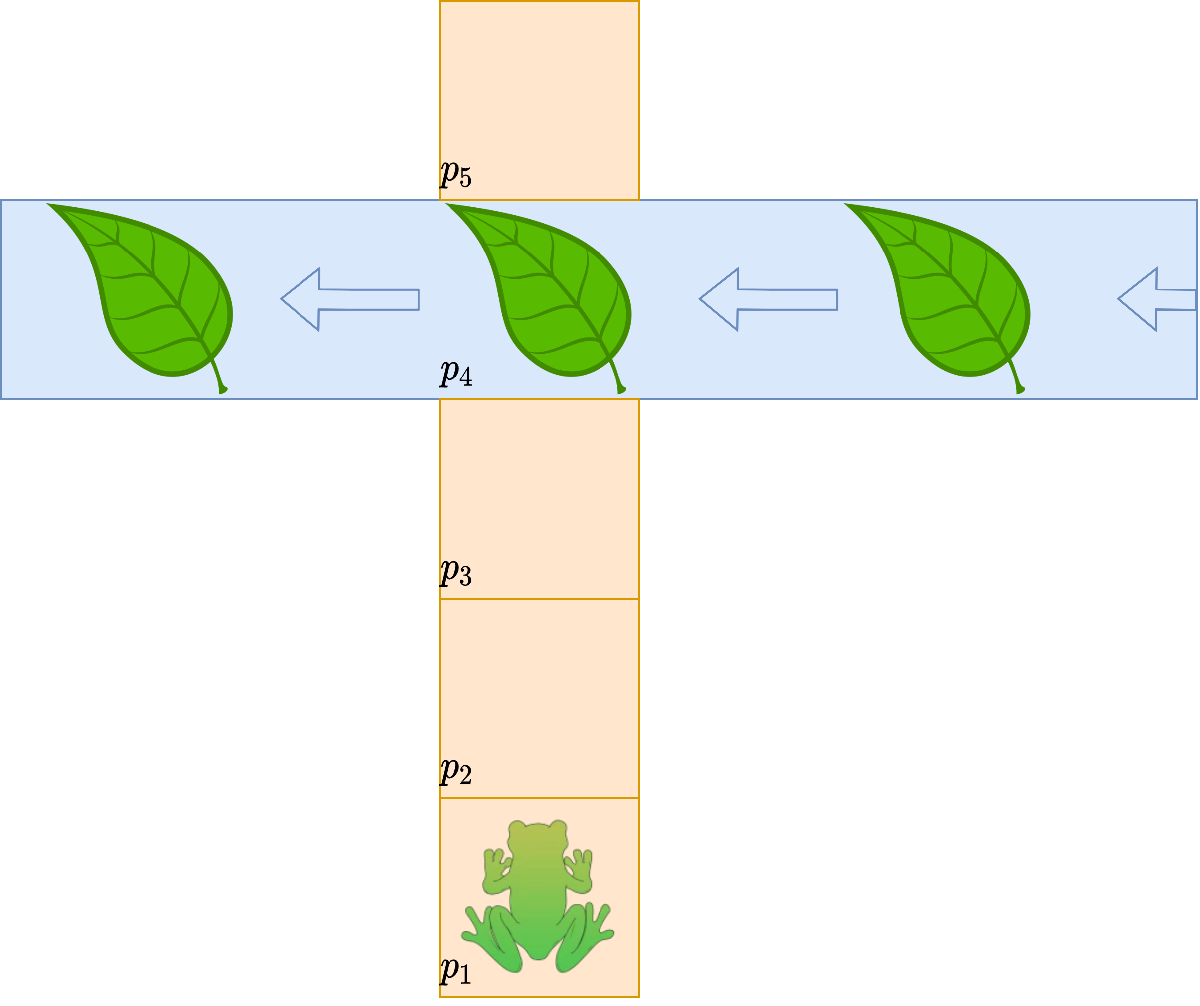

In the picture below is the transition system of the frog. Every state is a path fragment and he transitions between them with a jump. At state $\(p_3\)$ he can wait in front of the river and at state $\(p_5\)$ he has to wait because the path is at his end.

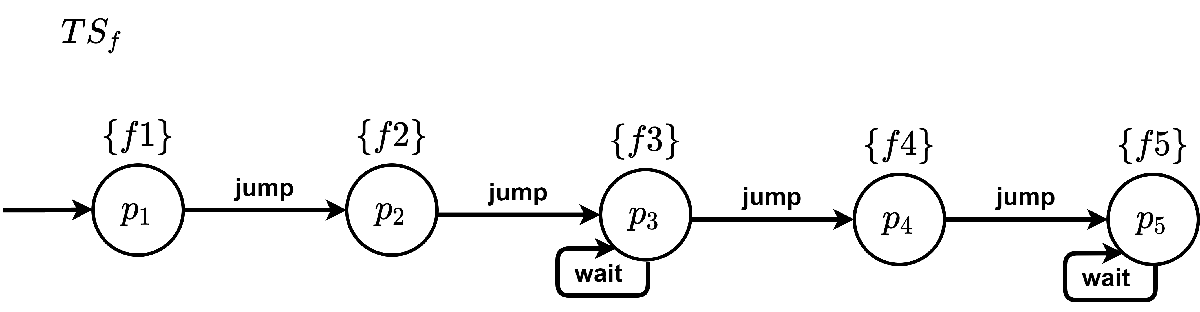

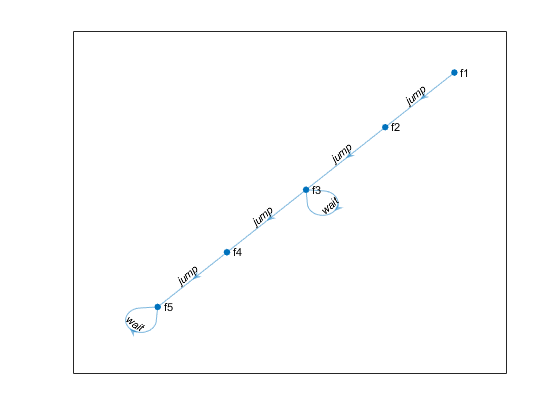

% States
S = ["p1" "p2" "p3" "p4" "p5"];

% Actions
Act = ["jump" "wait"];

% Transitions
% source | target | action
Tr =   [S(1) S(2) Act(1);
        S(2) S(3) Act(1);
        S(3) S(3) Act(2);
        S(3) S(4) Act(1);
        S(4) S(5) Act(1);
        S(5) S(5) Act(2);];

% Initial states
I = S(1);

% Atomic propositions
AP = ["f1" "f2" "f3" "f4" "f5"];

% Labels
L = [S' AP'];

% generate transition system
TSf = TransitionSystem(S, Act, Tr, I, AP, L);
TSf.plot();

The transition system of a leaf at path fragment $\(p_4\)$ is simpler. There is only the possibility that there is a leave or not and this state is constantly changing.

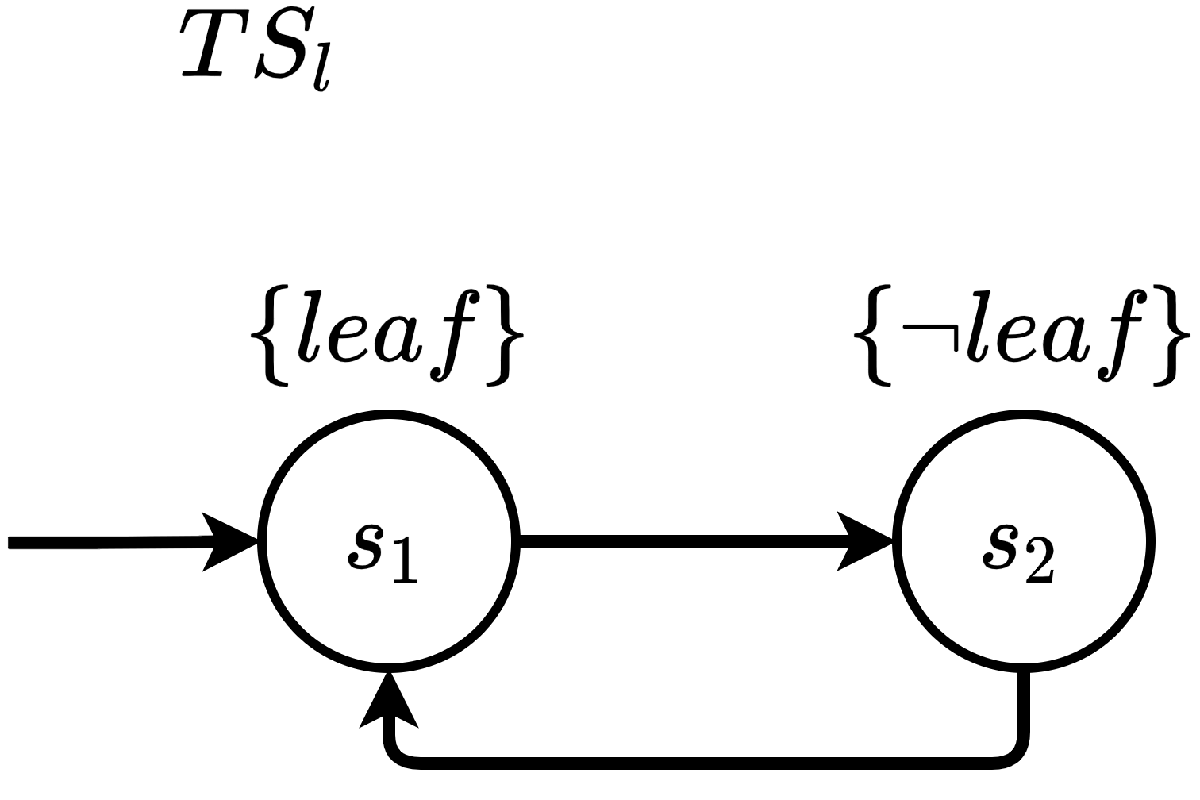

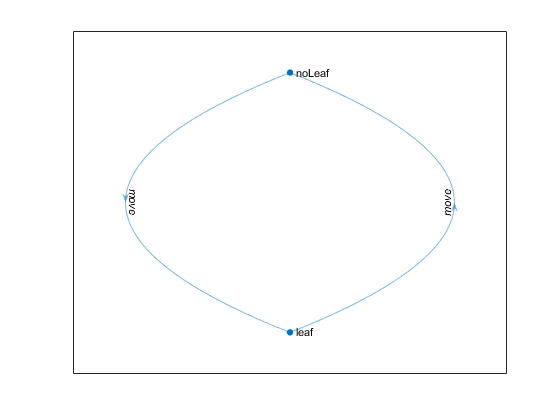

% States
S = ["s1" "s2"];

% Actions
Act = "move";

% Transitions
% source | target | action
Tr =   [S(1) S(2) Act(1);
        S(2) S(1) Act(1);];

% Initial states
I = S(1);

% Atomic propositions
AP = ["leaf" "noLeaf"];

% Labels
L = [S' AP'];

% generate transition system
TSl = TransitionSystem(S, Act, Tr, I, AP, L);
TSl.plot();

To get a system showing all possible states that could happen at the same time, the two transition systems have to be parallized.

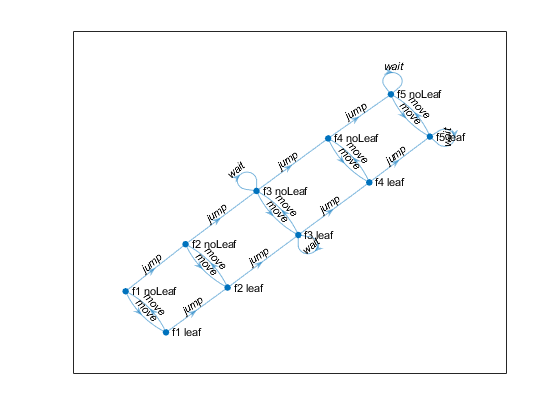

TSp = TransitionSystem.parallelize([TSf TSl]);
TSp.plot();

To make the example easier it is assumed that every time the frog takes an action the leave also moves. The result with all valid states and transitions is shown in the next picture.

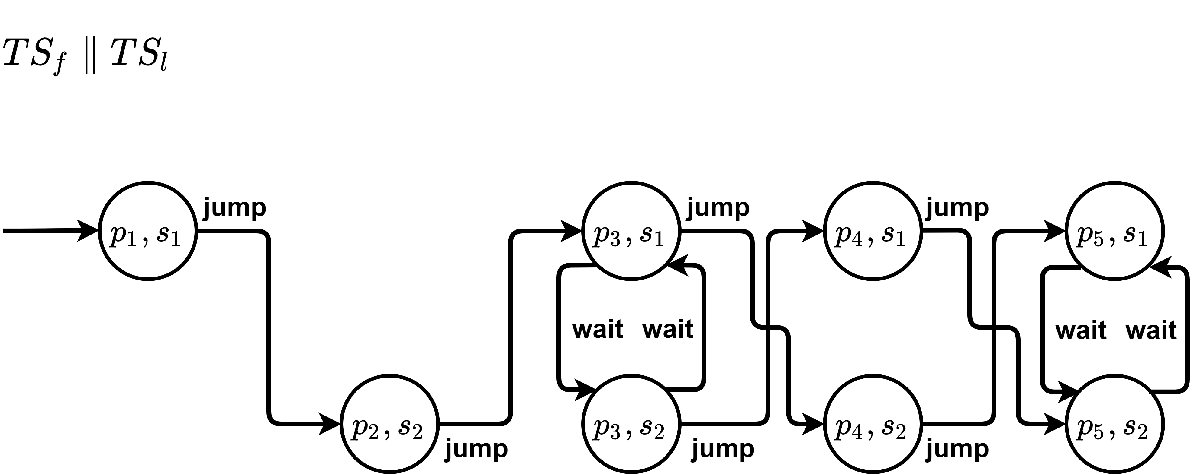

To prevent the frog from falling into water, the parallelized transition system $\(TS_p\)$ should not reach the state $\langle p_4,s_2 \rangle$ when the frog reaches the river but there is no leaf. This can be formulated in a safety property as LTL equation:


$$\varphi = \lnot(f_{4} \land \lnot leaf) \mathcal{U} f_{5}$$


State $f_4$ and $\lnot leaf$should not be true at the same time until the frog reaches state $f_5$.

Through online translators like [SPOT](https://spot.lrde.epita.fr/app/) this formular can be converted to a büchi automaton as shown in the next picture.

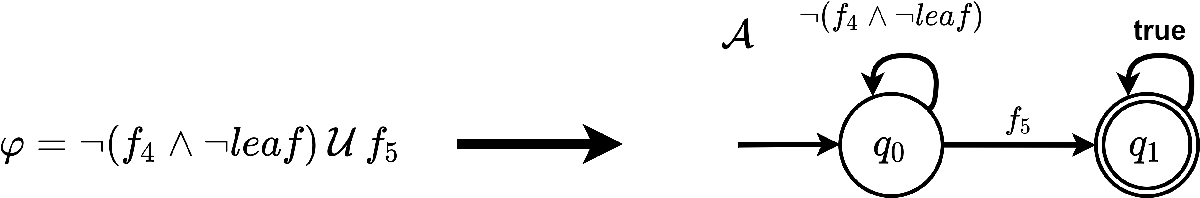

% States Q
states = ["q0" "q1"];

% Symbols Sigma (transition conditions)
% conditions for the transition between states

symbols = { @(allAPs) (~(allAPs.("f4") && allAPs.("noLeaf"))) ...
            @(allAPs) (allAPs.("f5")) ...
            @(allAPs) (1)};

% Transitions delta
transitions = {"q0" "q0" symbols{1}; ...
    "q0" "q1" symbols{2}; ...
    "q1" "q1" symbols{3}};

% Initial states
initialStates = "q0";

% Final states
finalStates = "q1";

% Construct Buchi Automata
BAsp = BuchiAutomata(states, symbols, transitions, initialStates, finalStates);

To apply the safety property in form of a büchi automata to the transition system. It has to synthesized with it. The result is a transition system that fulfills every time the safety property. 

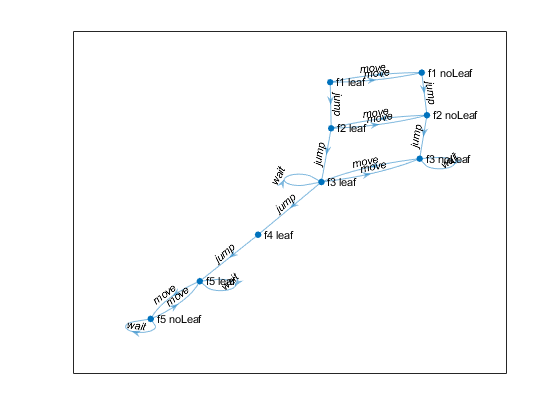

TSp.synthesizeWithBA(BAsp, true);
TSp.plot();

The result can be seen in the next picture. The green path shows an option to get to the end of the path.

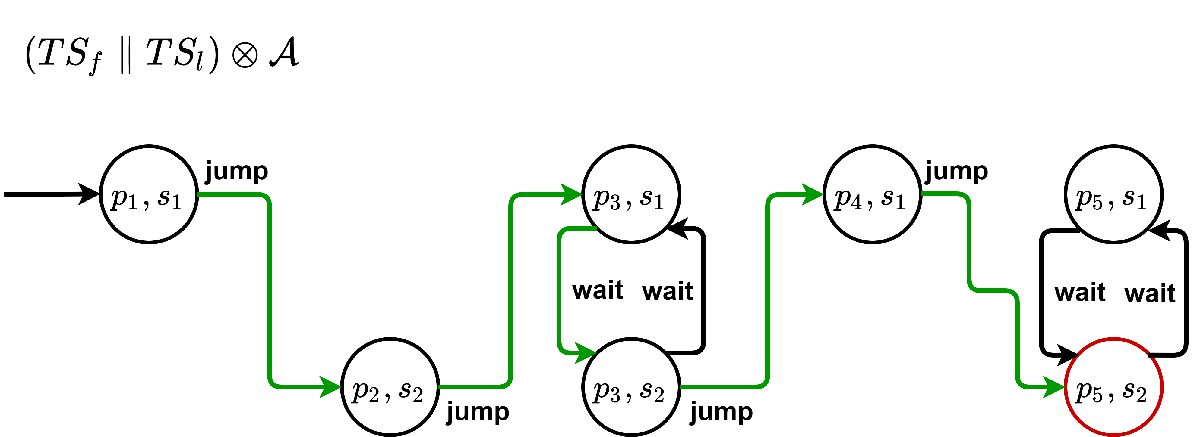

## Crossroad verification

### TSvehicle

### TScrossroad

### SafetyPropertyBA

## Functions for a verified crossroad transition system

### getTSvehicle.m

This function generates and outputs a transition system for a vehicle based on the direction that is used as an input for this method. The direction is the path that a vehicle uses for passing a crossroad.

dir = "ew" % Vehicle is heading from East to West.

dir = "ew"

This direction could be used to generate a transition system with states S, action Act, transitions Tr, initial states I, atomic propsitions AP and the labels L.

% States
S = ["i" "p" "o"];

% Actions
Act = ["g"+dir];

% Transitions
% source | target | action
Tr = [S(1) S(2) Act(1);
      S(2) S(3) Act(1);
      S(3) S(3) Act(1)];

% Initial states
I = [S(1)];

% Atomic propositions
AP = [S(1)+dir S(2)+dir S(3)+dir];

% Labels
L = [S' AP'];

### getTScrossroad.m

This function parallises the transition systems of the vehicles that are passing a crossroad at the same time. The input is not the single transition systems, only the directions are used to generate the single transition systems by itself.

vehDirs = ["ew" "wn"] % Vehicle 1 is heading from East to West. Vehicle 2 from west to north

vehDirs = 1×2 string array
    "ew"    "wn"


After generation of the vehicle transition systems they get parallelised in TSSynthesis. Because only two transition systems could be parallelised at once, this function has to be called more often.

% Get nr of vehicles
nrVeh = length(vehDirs);

% Generate Transition Systems for first vehicle
[S, Act, Tr, I, AP, L] = getTSvehicle(vehDirs(1));

Unrecognized function or variable 'getTSvehicle'.

% finished when only one vehicle
if nrVeh == 1
    return;
end
% Generate Transition Systems for the rest
for i = 2:nrVeh
    % generate TS for vehicle
    [Sv, Actv, Trv, Iv, APv, Lv] = getTSvehicle(vehDirs(i));
    
    [S, Act, Tr, I, AP, L] = TSSynthesis(S, Act, Tr, I, AP, L, Sv, Actv, Trv, Iv, APv, Lv);
end

### checkSafetyCondtion.m

This function checks if the safety condition is fulfilled. For that two paths of the safety condition are needed (pathA, pathB). Also the structure containing all atomic propositions and their values at this moment is needed. The last input is the number of the condtion that should be checked.

pathA = "pew"
pathB = "pwn"
% example atomic propositions structure
allAPs.iew = 1;
allAPs.iwn = 1;
allAPs.pew = 0;
allAPs.pwn = 0;
allAPs.oew = 0;
allAPs.own = 0;

equationNr = 1; % Equation number one should be checked

The output is the result of the selected equation. Is it possible to make a transtion in the system to state marked with allAPs (here state <input,input>) with the safety condition fulfilled.

if ~all(isfield(allAPs, [pathA pathB]))
    % Safety condition not relevant for this set of atomic propositions
    error("Wrong safety condition used for the model. Use only one where all atomic propositions contained in model.");
end

% directions of crossing vehicles
dir = extractAfter([pathA pathB],1);

% equations
if equationNr == 1
    result = ~(allAPs.(pathA) && allAPs.(pathB)) && ~allAPs.("o"+dir(1)) && ~allAPs.("o"+dir(2));
elseif equationNr == 2
    result = allAPs.("o"+dir(1)) || allAPs.("o"+dir(2));
elseif equationNr == 3
    result = 1;
else
    error("Equation does not exist. Wrong equation number used.");
end

### getBApaths.m

This function generates a buchi automata for a safety condition that should prevent two vehicles to drive on roads that are crossing. The input are two paths that are crossing. The output is the buchi automata with the states Q, transition conditions Sig, transitions delta, initial states Q0 and final states F.

crossingPath = ["pwe", "pwn"]; % The states passing from east to west and passing from west to north should not be reached at the same time.

With the crossing paths an anonymous function is generated, to allow the checking if this condition (the states are occupied) is fullfilled at runtime.

% States
Q = ["q0" "q1"];

    
% Sigma (transition conditions)
% make a safety function that could be accessed to check a transition
% condition
SF = @(allAPs, eqNr) checkSafetyCondition(crossingPath(1),crossingPath(2), allAPs, eqNr);

Sig = {@(allAPs) (SF(allAPs, 1)) ...
       @(allAPs) (SF(allAPs, 2)) ...
       @(allAPs) (SF(allAPs, 3))}; % the eqations are stored in  function safety condition

% Transitions
delta = {"q0" "q0" Sig{1}; ...
         "q0" "q1" Sig{2}; ... 
         "q1" "q1" Sig{3}};
    
% Initial states
Q0 = ["q0"];

% Final states
F = ["q1"];

### getVerfiedTS.m

To verify a crossroad transition system with forbidden directions, this function is used. The input is a transtion system to verify and the safety conditions crossing paths. For every row in crossing paths one safety condition is generated and then checked with the transition system. The output of this function is the verified transition system with only allowed states.

% Check which parts of TS are still valid with A
for i = 1:size(crossingPaths,1)
    % Generate the Büchi Automata for the current safety property
    [Q, Sig, delta, Q0, F] = getBApaths(crossingPaths(i,:));
    % Check if this safety property is relevant for this model
    if all(contains(crossingPaths(i,:), AP))
        % Verify the TS with BA
        [S, Act, Tr, I, AP, L] = TsACheck(S, Act, Tr, I, AP, L, Q, Sig, delta, Q0, F);
    end
end

## verifyWithModel.m

This function is used for verifing the actions of a crossroad manager. The crossroad manger inputs the vehicle directions that should pass the crossroad as atInput and the vehicles already on the crossroad atPassing.

atInput = ["ew" "ws"]; % Two vehicles that should pass the crossroad
atPassing = "se"; % One vehicle already on the crossroad
crossingPaths = ["pne", "pew";
                    "pne", "pwn";
                    "pne", "pes";
                    "pne", "psn";
                    "pne", "pwe";
                    "pne", "pse";
                    "pns", "pew";
                    "pns", "psw";
                    "pns", "pwn";
                    "pns", "pwe";
                    "pns", "pws";
                    "pns", "pes";
                    "pnw", "pew";
                    "pnw", "psw";
                    "pes", "psn";
                    "pes", "psw";
                    "pes", "pwe";
                    "pes", "pws";
                    "pew", "psn";
                    "pew", "pwn";
                    "pew", "psw";
                    "pen", "psn";
                    "pen", "pwn";
                    "psw", "pwe";
                    "psw", "pwn";
                    "psn", "pwe";
                    "psn", "pwn";
                    "pse", "pwe"];

A transtion model is build with the vehicle directions and checked with the third input the safety conditions crossing paths. The output is the result of the verfication. Are the actions of the crossroad manager valid or not.

if isempty(atInput) && isempty(atPassing)
    % no vehicle on crossroad
    verified = true;
    return;
end
% Get current state and directions from atInput and atPassing
directions = strings(0,0);
currentState = strings(1);
if ~isempty(atInput)
    directions = atInput;
    currentState = join(repmat("i",1,length(atInput)),"");
end
if ~isempty(atPassing)
    directions(end+1:end+length(atPassing)) = atPassing;
    currentState = currentState + join(repmat("p",1,length(atPassing)),"");
end

% Generate Transition System for the crossroad
[S, Act, Tr, I, AP, L] = getTScrossroad(directions);

% Generate a verified Transition System with Büchi Automata
[S, Act, Tr, I, AP, L] = getVerifiedTS(S, Act, Tr, I, AP, L, crossingPaths);

% check if state exists
if any(currentState == S)
    % get all actions that should be done
    currentActions = Act(contains(Act,directions(1,:)));
    % check all actions
    for i=1:length(currentActions)
        if any(all([currentState currentActions(i)] == Tr(:,[1 3]),2))
            % action exists!! :)
            % go to state corresponding to this action
            currentState = Tr(all([currentState currentActions(i)] == Tr(:,[1 3]),2),2);
        else
            verified = false;
            return
        end
    end
    % all actions are possible
    verified = true;
else
    verified = false;
end

## Example

With this example it possible to build a verfied transition system for 1-4 vehicles on a 4 lane crossroad. To show the digraph comment line under the wanted number of vehicles out.

% Directions of vehicles
% 1 vehicle
%dirs = ["ew"];
% 2 vehicle
%dirs = ["ew","wn"];
% 3 vehicle
dirs = ["ew","wn","nw"];
% 4 vehicle
%dirs = ["ew","wn","nw","se"];

% Generate Transition System for the crossroad
[S, Act, Tr, I, AP, L] = getTScrossroad(dirs);

% Plot the crossroad TS
plotTS(S, Act, Tr, I, AP, L);

% array with paths that are crossing in each line        
crossingPaths = ["pne", "pew";
                 "pne", "pwn";
                 "pne", "pes";
                 "pne", "psn";
                 "pne", "pwe";
                 "pne", "pse";
                 "pns", "pew";
                 "pns", "psw";
                 "pns", "pwn";
                 "pns", "pwe";
                 "pns", "pws";
                 "pns", "pes";
                 "pnw", "pew";
                 "pnw", "psw";
                 "pes", "psn";
                 "pes", "psw";
                 "pes", "pwe";
                 "pes", "pws";
                 "pew", "psn";
                 "pew", "pwn";
                 "pew", "psw";
                 "pen", "psn";
                 "pen", "pwn";
                 "psw", "pwe";
                 "psw", "pwn";
                 "psn", "pwe";
                 "psn", "pwn";
                 "pse", "pwe"];          

% Generate a verified Transition System with Büchi Automata
[S, Act, Tr, I, AP, L] = getVerifiedTS(S, Act, Tr, I, AP, L, crossingPaths);

% Plot the verified TS
plotTS(S, Act, Tr, I, AP, L);